load("DirtyValidNet.mat")

symbols = image2symbols(img1,net1.DirtyValidNet,20);
RGBsym = symbol2RGB(symbols);
realPoints  = [0,144,44 ; 0,164,111 ; 0,255,85 ; 255,242,150 ; 255,0,255 ; 0,228,245 ; 225,0,128 ; 255,0,0]
idx = [];
for i = 1:400 
    foundPoints = cell2mat(RGBsym(i));
     idx = [idx, knnsearch(realPoints,foundPoints)];   
end
idx = idx - 1;

trans = '250641451005016233665145306720402167256431267142312711471004250233667553100675461005215031220101310731453347216534462563100675461005155031271154336615531004415733066545346064123047444024664562100405623506416534420103336671413342010433674554312064121202146115220151334201573527104034662562322625631006117110051551344201013447215035271040206675563026704021067571330624510320501502441557340745623226355035020154302735631006056231220143320605563166455631620141330660403367314534420164320624403566756233062056100411451007156534462440350674403066414530665440350641450320514333670171344645473207204033140161260146132165064141736440677142606621415142240221371563614412670014410175312724313027356310063157344201713367256210061557352671643447444030462546336711451006215735667154336605443226714710067562100711453106456335071151304725643226714703205164320645631006756210060556362201573506414534420120344675523126156410043565350625563046256231620145204675573262701502406412250641513462015031260544312710403466415735266144100611451007215031220146322711633502016432064556316201633126255610073550312670403546454535664556316201643206456310050162336651453067201502443565350625563046256231620146322661451342004024066145302715451006215710067157350201623126655735462440322720561002010433620156336104573232431043654504670430034344460124707445153011120313161567304327004436157211722335020143320605563166244033671040312621513502016432062415024641453026214534420167322721503367256410073562322721643126704034062562332645633466455733427015024064122406614530271545100711453026204035064145100211543126354133020163332605543302016034464556350260421006055631020157350641453442015133463157344665413506455733420141304675653502016432062415024625023366755310060556310201203446755231261564100435653506255630462562316201413502016432062440304675643506755510067546100721503227144031464554312270401004455630666165310625441006456303205151332701573447214133472040322671463367115530272151336670403027471023152032045555230122705302203125700316662340432317374363233673145373375664605230304675653502017133672562100715603126155131464543100711513166416434620141334620403446256335071151306721513366716310064556032051503367344035064145100631513306244033260571100611451007256331262056100201313367244030660556100605543466744031464556310201573527204030261157352720403206756710072157100665413266244030206412310675563027215133667040350674402407115732462543350201073527214533461145344634541006055631020150336734403506744031662564100645563546755435462544134064120320501502425052256625543066755531220124336201243206244025667562330620403366304021471145312201203306055133420126302671513306614110051514212636772457744104207264654753561345034712223663743163436642565537160754353466712126614530672162336671513062012431274164346250520320501502425052312411573366556310051145302621413046614510041171100411573506404022072555302671631006055631020102362201033366656035272145344714541005155133461545100304711563045212406412032050521242505212452150312715451006250233667553346201273127114510050162312701413446254410041171100521503367256330267144346201573142012633666165334721453127116310225052124250520320501502406412250645643306247210052150312201013107314533472165344625631006754610051550312711543366155310044157330665453460641203205101352721503367107210051551344201013447215035271040206532503501773214704045641444274311672275763343754175607552633663564627040054626575746633667141334201043367455431206412032051223126614530271545100421413506247210046541344615501302006116234471100201332124115733665440106304661543053503205133232675633502016231261545334721543622016534062141350625441642011633673145332611453442006216226040144300601445641502406412212621513506455733435040142310150240641223060556316725413166247210042556316661513466401502406412206641413446054335062562100715453502014533461557310645563163504020251503222444150240641212425052100515242025112410047506100521102122012024447512212415241004352525042516204425222162010520447517226260402504410510040504254425162511541476671674641064406365742034527764254512436320316067473350532161232223765715236636252511052462011721420123220425222304750322620110236461152125144012425052032050150240000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000155716141226574626463304627232606110045017275444013420124175540013447056771214571054700000000000000000000000000000000000000000';
trans2  = [];
for i = 1:400
    trans2 = [trans2, str2double(trans(i))];
end

[a b c] = symerr(idx,trans2);
find(c==1)
acc = 100 - b*100

symbols = image2symbols(cell2mat(data(12)),net1.DirtyValidNet,20);
RGBsym = symbol2RGB(symbols);
rec = [];
for j = 1:400
    lst  = [];
    foundPoints = cell2mat(RGBsym(j));
    for i = 1:8
        lst = [lst , norm(realPoints(i,:) - foundPoints)];
    end
    NN = find(lst == min(lst));
    rec = [rec, NN];
end

rec = rec - 1;
[a b c] = symerr(rec,trans2(4401:4800));
find(c==1);
acc = 100 - b*100

acc = 99

rec = [];
i = 13;
for k = 1:i-1
    
    img = cell2mat(data(k));
    symbols = image2symbols(img1,net1.DirtyValidNet,20);
    RGBsym = symbol2RGB(symbols);

    for j = 1:400
        lst  = [];
        foundPoints = cell2mat(RGBsym(j));
        for w = 1:8
            lst = [lst , norm(realPoints(w,:) - foundPoints)];
        end
        NN = find(lst == min(lst));
        rec = [rec, NN];
    end
end

rec = rec - 1

rec =      2     5     0     6     4     0     4     5     0     0     0     5     0     0     6     2     3     3     6     6     5     0     4     5     3     0     6     7     2     0     4     0     2     0     6     7     2     5     6     4     3     0     2     6     7     0     4     2     3     0


trans = '250641451005016233665145306720402167256431267142312711471004250233667553100675461005215031220101310731453347216534462563100675461005155031271154336615531004415733066545346064123047444024664562100405623506416534420103336671413342010433674554312064121202146115220151334201573527104034662562322625631006117110051551344201013447215035271040206675563026704021067571330624510320501502441557340745623226355035020154302735631006056231220143320605563166455631620141330660403367314534420164320624403566756233062056100411451007156534462440350674403066414530665440350641450320514333670171344645473207204033140161260146132165064141736440677142606621415142240221371563614412670014410175312724313027356310063157344201713367256210061557352671643447444030462546336711451006215735667154336605443226714710067562100711453106456335071151304725643226714703205164320645631006756210060556362201573506414534420120344675523126156410043565350625563046256231620145204675573262701502406412250641513462015031260544312710403466415735266144100611451007215031220146322711633502016432064556316201633126255610073550312670403546454535664556316201643206456310050162336651453067201502443565350625563046256231620146322661451342004024066145302715451006215710067157350201623126655735462440322720561002010433620156336104573232431043654504670430034344460124707445153011120313161567304327004436157211722335020143320605563166244033671040312621513502016432062415024641453026214534420167322721503367256410073562322721643126704034062562332645633466455733427015024064122406614530271545100711453026204035064145100211543126354133020163332605543302016034464556350260421006055631020157350641453442015133463157344665413506455733420141304675653502016432062415024625023366755310060556310201203446755231261564100435653506255630462562316201413502016432062440304675643506755510067546100721503227144031464554312270401004455630666165310625441006456303205151332701573447214133472040322671463367115530272151336670403027471023152032045555230122705302203125700316662340432317374363233673145373375664605230304675653502017133672562100715603126155131464543100711513166416434620141334620403446256335071151306721513366716310064556032051503367344035064145100631513306244033260571100611451007256331262056100201313367244030660556100605543466744031464556310201573527204030261157352720403206756710072157100665413266244030206412310675563027215133667040350674402407115732462543350201073527214533461145344634541006055631020150336734403506744031662564100645563546755435462544134064120320501502425052256625543066755531220124336201243206244025667562330620403366304021471145312201203306055133420126302671513306614110051514212636772457744104207264654753561345034712223663743163436642565537160754353466712126614530672162336671513062012431274164346250520320501502425052312411573366556310051145302621413046614510041171100411573506404022072555302671631006055631020102362201033366656035272145344714541005155133461545100304711563045212406412032050521242505212452150312715451006250233667553346201273127114510050162312701413446254410041171100521503367256330267144346201573142012633666165334721453127116310225052124250520320501502406412250645643306247210052150312201013107314533472165344625631006754610051550312711543366155310044157330665453460641203205101352721503367107210051551344201013447215035271040206532503501773214704045641444274311672275763343754175607552633663564627040054626575746633667141334201043367455431206412032051223126614530271545100421413506247210046541344615501302006116234471100201332124115733665440106304661543053503205133232675633502016231261545334721543622016534062141350625441642011633673145332611453442006216226040144300601445641502406412212621513506455733435040142310150240641223060556316725413166247210042556316661513466401502406412206641413446054335062562100715453502014533461557310645563163504020251503222444150240641212425052100515242025112410047506100521102122012024447512212415241004352525042516204425222162010520447517226260402504410510040504254425162511541476671674641064406365742034527764254512436320316067473350532161232223765715236636252511052462011721420123220425222304750322620110236461152125144012425052032050150240000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000155716141226574626463304627232606110045017275444013420124175540013447056771214571054700000000000000000000000000000000000000000';
trans2  = [];
for i = 1:4800
    trans2 = [trans2, str2double(trans(i))];
end
[a b c] = symerr(rec,trans2);
find(c==1);
acc = 100 - b*100

acc = 28.6667

%% use this 
rec = [];
numSymbols = 20;
realPoints  = [0,144,44 ; 0,164,111 ; 0,255,85 ; 255,242,150 ; 255,0,255 ; 0,228,245 ; 225,0,128 ; 255,0,0]

realPoints =      0   144    44
     0   164   111
     0   255    85
   255   242   150
   255     0   255
     0   228   245
   225     0   128
   255     0     0


i = 13;
for k = 1:i-1
    symbols = image2symbols(cell2mat(data(k)),net1.DirtyValidNet,numSymbols);
    RGBsym = symbol2RGB(symbols);
    for j = 1:numSymbols*numSymbols
        lst  = [];
        foundPoints = cell2mat(RGBsym(j));
        for w = 1:length(realPoints)
            lst = [lst , norm(realPoints(w,:) - foundPoints)];
        end
        NN = find(lst == min(lst));
        rec = [rec, NN];
    end
    end
rec = rec - 1;
[a b c] = symerr(rec,trans2);
find(c==1);
acc = 100 - b*100

acc = 92

% [labeledImage, numberOfBlobs] = bwlabel(featureMap);
% blobMeasurements = regionprops(labeledImage, 'area', 'Centroid');
% % Get all the areas
% allAreas = [blobMeasurements.Area]; % No semicolon so it will print to the command window.
% menuOptions{1} = '0'; % Add option to extract no blobs.
% % Display areas on image
% for k = 1 : numberOfBlobs           % Loop through all blobs.
%   thisCentroid = [blobMeasurements(k).Centroid(1), blobMeasurements(k).Centroid(2)];
%   message = sprintf('Area = %d', allAreas(k));
%   text(thisCentroid(1), thisCentroid(2), message, 'Color', 'r');
%   menuOptions{k+1} = sprintf('%d', k);
% end

numberToExtract = 1;
% sizeOption = 'Largest';

featureMap = ExtractNLargestBlobs(featureMap, numberToExtract);


% featureMap = edge(featureMap,"approxcanny");  % extract perimeter of frame (maybe lose if acc low)

K = (1/25)*ones(5); % smooth factor
featureMap = conv2(featureMap,K,'same');

figure;
image(featureMap.*255)  % display feature map

[featureMap,J]=find(featureMap>max(featureMap(:))/2);
IJ=[featureMap,J];
[~,idx]=min(IJ*[1 1; -1 -1; 1 -1; -1 1].');
corners=IJ(idx,:);

% display corners of the frame superimposed over the image
imshow(I)
hold on
plot(corners(1,2),corners(1,1),'r+')
plot(corners(2,2),corners(2,1),'r+')
plot(corners(3,2),corners(3,1),'r+')
plot(corners(4,2),corners(4,1),'r+')
hold off

% Apply Perspective Warping followed by cropping of the frame 
movingPoints = [corners(1,2) corners(1,1); corners(3,2),corners(3,1); corners(2,2),corners(2,1); corners(4,2),corners(4,1)];%coordinate of distorted corners 
fixedPoints=[0 0;size(I,1) 0;size(I,1) size(I,2);0 size(I,2)]; %coordinate of image's corners

tform = fitgeotrans(movingPoints,fixedPoints,'projective');
R=imref2d(size(I),[1 size(I,1)],[1 size(I,2)]);
frame=imwarp(I,tform,'OutputView',R);

figure
imshow(frame);

% Apply grid for visual analysis (Remove for final code)
numSymbols = 20;
figure
imshow(frame);
axis on;
[rows, columns, numberOfColorChannels] = size(frame)
hold on;
for row = 1 : rows/numSymbols : rows
  line([1, columns], [row, row], 'Color', 'k');
end
for col = 1 : columns/numSymbols : columns
  line([col, col], [1, rows], 'Color', 'k');
end

% Divide Frames into symbols
[rows columns numberOfColorBands] = size(frame);
blockSizeR = rows/numSymbols; % Rows in block.
blockSizeC = columns/numSymbols; % Columns in block.

wholeBlockRows = floor(rows / blockSizeR);
blockVectorR = [blockSizeR * ones(1, wholeBlockRows), rem(rows, blockSizeR)] ;
blockVectorR = blockVectorR(1:numSymbols);
% Figure out the size of each block in columns.
wholeBlockCols = floor(columns / blockSizeC);
blockVectorC = [blockSizeC * ones(1, wholeBlockCols), rem(columns, blockSizeC)];
blockVectorC = blockVectorC(1:numSymbols);
symbols = mat2cell(frame, blockVectorR, blockVectorC, numberOfColorBands)

% display one symbol
symbol1 = cell2mat(symbols(1,2));
figure
image(symbol1)

R = mean2(symbol1(:,:,1))
G = mean2(symbol1(:,:,2))
B = mean2(symbol1(:,:,3))

XYZ  = rgb2xyz([R/255,G/255,B/255],'WhitePoint','D65','ColorSpace','sRGB')
% XYZ = xyz2rgbwide(XYZ)
x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3))
y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3))
xyz2rgb(XYZ).*255

lab = rgb2lab([R/255,G/255,B/255])
C = makecform('srgb2lab');
lab = applycform([R/255,G/255,B/255],C)

rowVals = [];
colVals = [];
 oneSymbol = symbol1;
        meanR = mean2(oneSymbol(:,:,1));
        meanG = mean2(oneSymbol(:,:,2));
        meanB = mean2(oneSymbol(:,:,3));
        
        XYZ = rgb2xyz([meanR/255,meanG/255,meanB/255]);
        CC = makecform('xyz2xyl');
        xy = applycform(XYZ,CC)
        
        % 0.34
        
        if xy(1) > 0.34
            rowVals = [rowVals,xy(1) + xy(3)]
        else
            rowVals = [rowVals,xy(1) - xy(3)]
        end
        
        if xy(2) > 0.34
            colVals = [colVals,xy(2) + xy(3)]
        else
            colVals = [colVals,xy(2) - xy(3)]
        end
        

   symbols  = image2symbols(I, net, 20)


CC = makecform('xyz2xyl')
applycform(XYZ,CC)

% 
% rgbvalue = uint16([R,G,B])
% xyzvalue = rgbwide2xyz(rgbvalue,10)
% x = xyzvalue(1)/(xyzvalue(1)+xyzvalue(2)+xyzvalue(3))
% y = xyzvalue(2)/(xyzvalue(1)+xyzvalue(2)+xyzvalue(3))


% xyz_primaries = rgb2xyz([R/255 G/255 B/255])
% xyzMag = sum(xyz_primaries,2)
% x_primary = xyz_primaries(:,1)./xyzMag
% y_primary = xyz_primaries(:,2)./xyzMag


[x,y] = findxy(symbols)
figure;
plotChromaticity();
hold on;
plot(y,x,'*');
hold off

% Categorize colours
% symbol1(12,16,:);
% meanR = mean(mean(symbol1(:,:,1)));
% meanG = mean(mean(symbol1(:,:,2)));
% meanB = mean(mean(symbol1(:,:,3)));
% 
% %take inner two eights of symbol 
% meanR = mean(mean(symbol1(9:15,12:20,1)))
% meanG = mean(mean(symbol1(9:15,12:20,2)))
% meanB = mean(mean(symbol1(9:15,12:20,3)))
% 
% XYZ = rgb2xyz([meanR,meanG,meanB]);
% x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3));
% y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3));
% 
% xideal = 0.1725;
% yideal = 0.3052;

xideal = [0.011 0.06367 0.2503 0.4008 0.169 0.1725 0.449 0.729];
yideal = [0.733,0.491, 0.579, 0.4127, 0.007, 0.3052, 0.139, 0.271];
[rowVals, colVals] = generatePointsCIE(symbols);
% convert RGB value to integer for signal constellation and used knn to
figure;
plotChromaticity();
hold on;
plot(rowVals,colVals,'*');
plot(xideal, yideal,'kx','LineWidth',3);
hold off

foundPoints = [colVals; rowVals;]'; % (x,y)
realPoints  = [0.011 0.06367 0.2503 0.4008 0.169 0.1725 0.449 0.729; 0.733,0.491, 0.579, 0.4127, 0.007, 0.3052, 0.139, 0.271 ]';

% A = rand(1,2)
% B = rand(10,2)
% %compute Euclidean distances:
% distances = sqrt(sum(bsxfun(@minus, B, A).^2,2))
% %find the smallest distance and use that as an index into B:
% closest = B(find(distances==min(distances)),:)
% figure;
% plot(A(1),A(2),'*')
% hold on
% plot(B(:,1)', B(:,2)','kx','LineWidth',3);

[k,dist] = dsearchn(realPoints, foundPoints);

assumedPoints = []; %zeros(400,2)
for i = 1:1:200
    assumedPoints = [assumedPoints; realPoints(k(i),:)];
end


hold off
figure;
plotChromaticity();
hold on;
plot(assumedPoints(:,1), assumedPoints(:,2),'kx','LineWidth',3);
hold off

% Function to return the specified number of largest or smallest blobs in a binary image.
% If numberToExtract > 0 it returns the numberToExtract largest blobs.
% If numberToExtract < 0 it returns the numberToExtract smallest blobs.
% Example: return a binary image with only the largest blob:
%   binaryImage = ExtractNLargestBlobs(binaryImage, 1)
% Example: return a binary image with the 3 smallest blobs:
%   binaryImage = ExtractNLargestBlobs(binaryImage, -3)

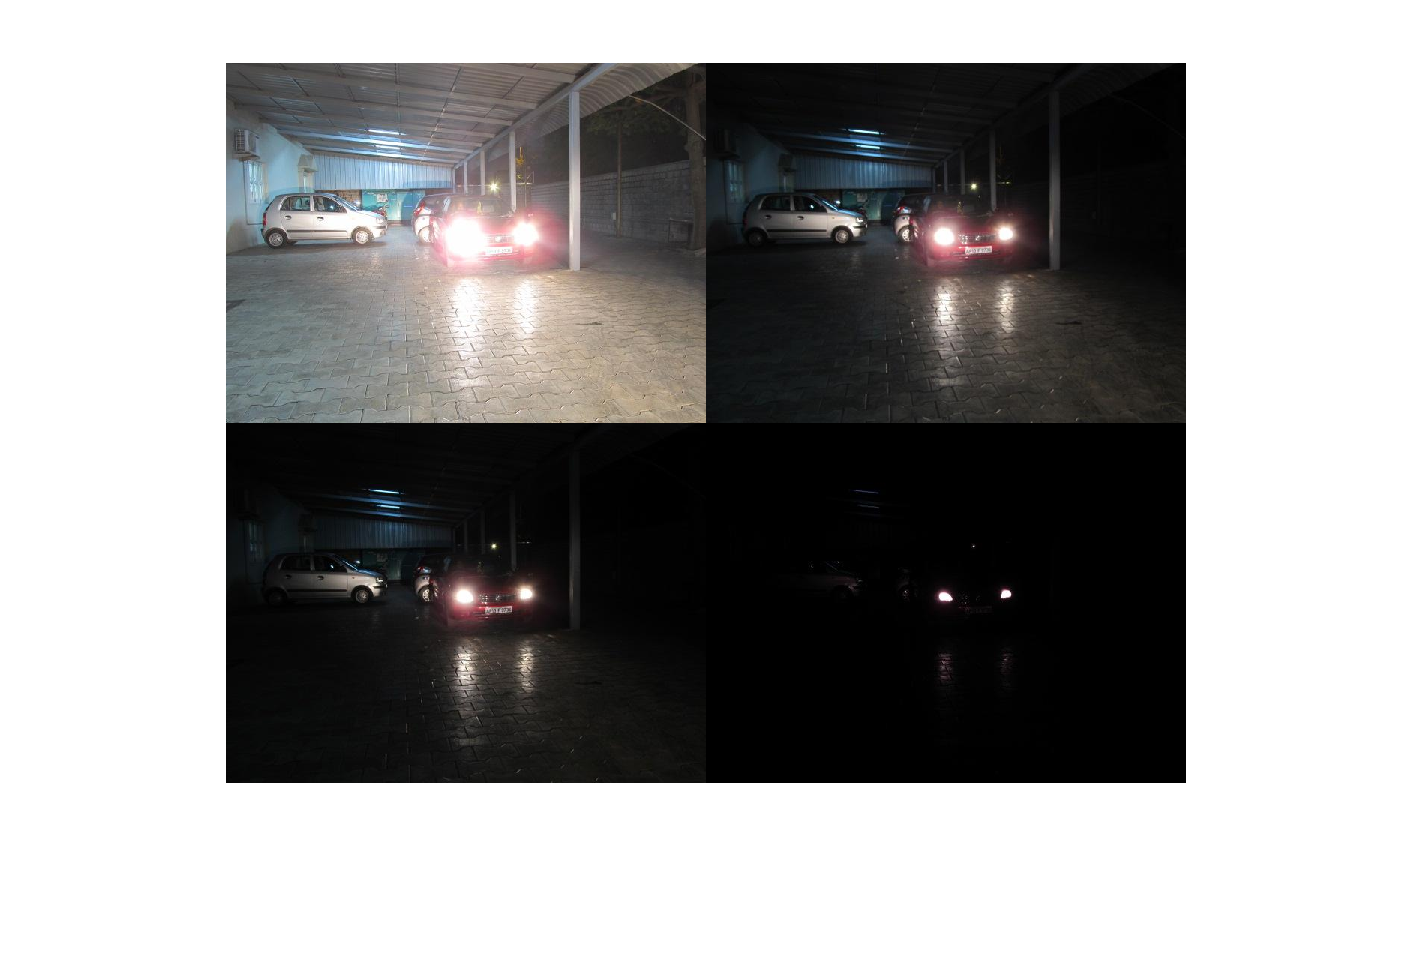

I1 = imread('car_1.jpg');
I2 = imread('car_2.jpg');
I3 = imread('car_3.jpg');
I4 = imread('car_4.jpg');
montage({I1,I2,I3,I4})

E = blendexposure(I1,I2,I3,I4);

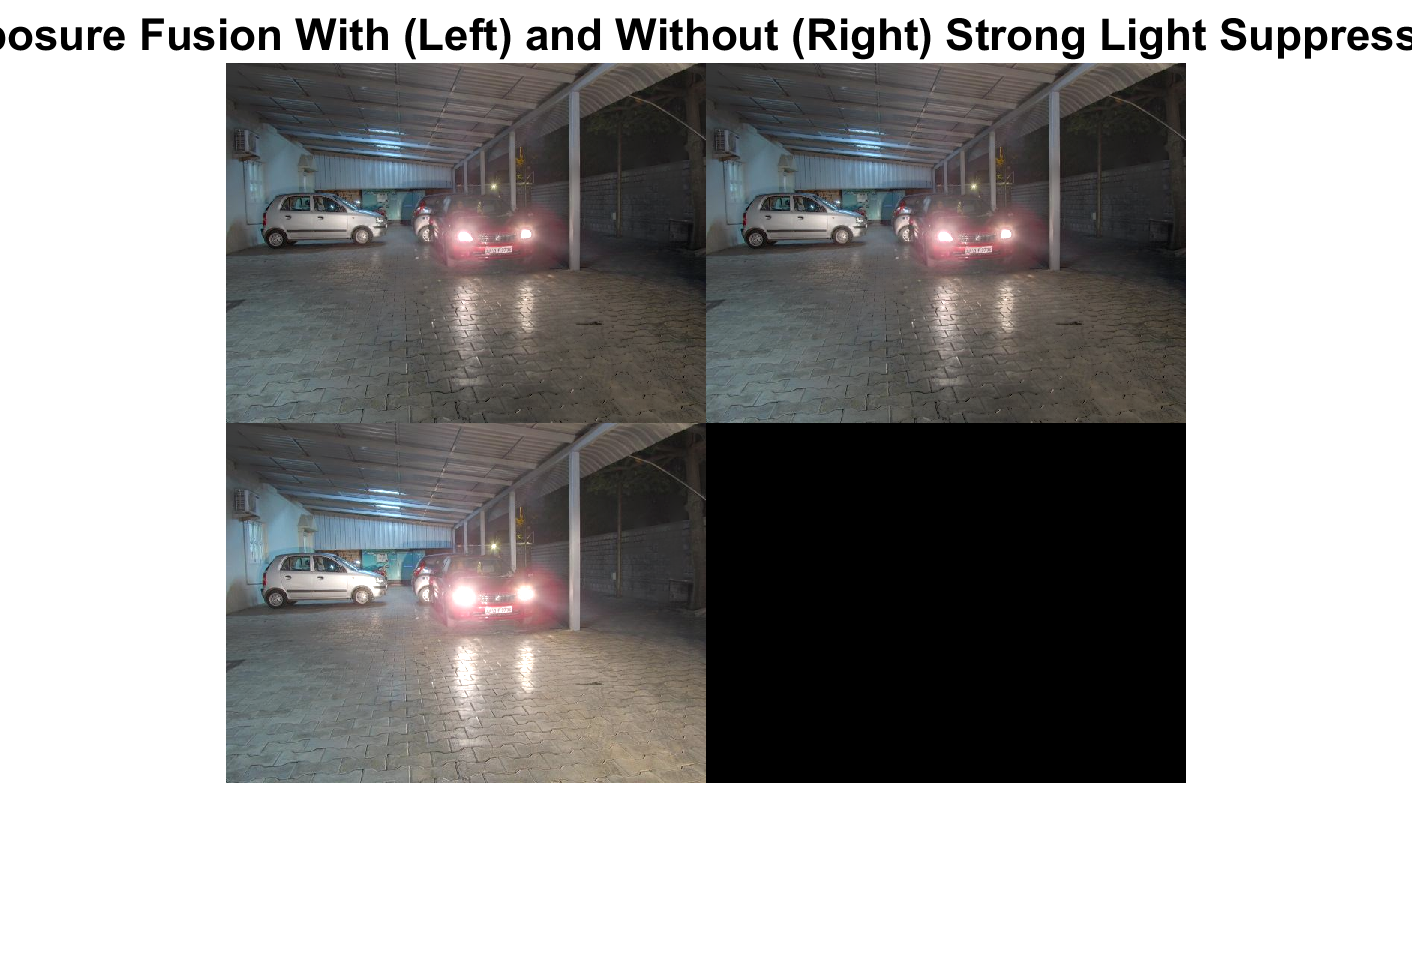

F = blendexposure(I1,I2,I3,I4,'ReduceStrongLight',true);
G = blendexposure(I1,I2,I3,I4,'contrast',0.8,...
    'saturation',0.8,'wellexposedness',0.8,'reduceStrongLight',false);

montage({E,F,G})
title('Exposure Fusion With (Left) and Without (Right) Strong Light Suppression')

img1 = cell2mat(data(1));
figure;
img1 = imadjust(img1,stretchlim(img1),[]);
imshow(img1)

function binaryImage = ExtractNLargestBlobs(binaryImage, numberToExtract)
try
  % Get all the blob properties.  Can only pass in originalImage in version R2008a and later.
  [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
  blobMeasurements = regionprops(labeledImage, 'area');
  % Get all the areas
  allAreas = [blobMeasurements.Area];
  if numberToExtract > 0
    % For positive numbers, sort in order of largest to smallest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'descend');
  elseif numberToExtract < 0
    % For negative numbers, sort in order of smallest to largest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'ascend');
    % Need to negate numberToExtract so we can use it in sortIndexes later.
    numberToExtract = -numberToExtract;
  else
    % numberToExtract = 0.  Shouldn't happen.  Return no blobs.
    binaryImage = false(size(binaryImage));
    return;
  end
  % Extract the "numberToExtract" largest blob(a)s using ismember().
  biggestBlob = ismember(labeledImage, sortIndexes(1:numberToExtract));
  % Convert from integer labeled image into binary (logical) image.
  binaryImage = biggestBlob > 0;
catch ME
  errorMessage = sprintf('Error in function ExtractNLargestBlobs().\n\nError Message:\n%s', ME.message);
  fprintf(1, '%s\n', errorMessage);
  uiwait(warndlg(errorMessage));
end
end
function [rowVals, colVals] = findxy(symbols)

   rowVals = [];
   colVals = [];
   for row = 1:20
    for col = 1:20
        oneSymbol = cell2mat(symbols(row,col));
        meanR = mean2(oneSymbol(:,:,1));
        meanG = mean2(oneSymbol(:,:,2));
        meanB = mean2(oneSymbol(:,:,3));
        
        XYZ = rgb2xyz([meanR/255,meanG/255,meanB/255]);
        CC = makecform('xyz2xyl');
        xy = applycform(XYZ,CC);
        
        % 0.34
        
%         if xy(1) > 0.34
%             rowVals = [rowVals,xy(1) - xy(3)];
%         else
%             rowVals = [rowVals,xy(1) + xy(3)];
%         end
%         
%         if xy(2) > 0.34
%             colVals = [colVals,xy(2) - xy(3)];
%         else
%             colVals = [colVals,xy(2) + xy(3)];
%         end
       
    end
end
end

function [RGBcell] = symbol2RGB(symbols)
RGBcell = {1,400};
temp = zeros(1, 3);
i = 1;
for row = 1:20
    for col = 1:20
        oneSymbol = cell2mat(symbols(row,col));
        
%         meanR = mean2(oneSymbol(:,:,1))/255;
%         meanG = mean2(oneSymbol(:,:,2))/255;
%         meanB = mean2(oneSymbol(:,:,3))/255;
%         
         meanR = mean2(oneSymbol(9:15,8:24,1));
         meanG = mean2(oneSymbol(9:15,8:24,2));
         meanB = mean2(oneSymbol(9:15,8:24,3));
        
        temp(:,1) = meanR;
        temp(:,2) = meanG;
        temp(:,3) = meanB;
        
        RGBcell{i} = temp;
        i = i + 1;
        
    end
end
end

function [rowVals, colVals] = generatePointsCIE(symbols)
rowVals = [];
colVals = [];
for row = 1:20
    for col = 1:20
        oneSymbol = cell2mat(symbols(row,col))
%         meanR = mean2(oneSymbol(9:15,8:24,1));
%         meanG = mean2(oneSymbol(9:15,8:24,2));
%         meanB = mean2(oneSymbol(9:15,8:24,3));
%         
%         meanR = mean2(oneSymbol(6:18,8:24,1));
%         meanG = mean2(oneSymbol(6:18,8:24,2));
%         meanB = mean2(oneSymbol(6:18,8:24,3));
        meanR = mean2(oneSymbol(:,:,1))/255;
        meanG = mean2(oneSymbol(:,:,2))/255;
        meanB = mean2(oneSymbol(:,:,3))/255;
        
        XYZ = rgb2xyz([meanR,meanG,meanB]);
        x = XYZ(1)/(XYZ(1)+XYZ(2)+XYZ(3));
        y = XYZ(2)/(XYZ(1)+XYZ(2)+XYZ(3));
        rowVals = [rowVals,x];
        colVals = [colVals,y];
        
    end
end
end